# Image Category

## Load Images

imgDs = imageDatastore('C:\Users\rektplorer64\OneDrive\Documents\MUICT Works\YEAR 4\ITCS476 - Digital Image Processing\Project 1 - Thai Food Image Recognition\datasets\FINAL DATASET', ...
    'FileExtensions', {'.jpg'}, ...
    'IncludeSubfolders',true, ...
    'LabelSource',"foldernames", "ReadFcn", @scaleimage)

imgDs =   ImageDatastore with properties:

                       Files: {
                              ' ...\barbecued_red-ThaiFoodDataset-001.jpg';
                              ' ...\barbecued_red-ThaiFoodDataset-002.jpg';
                              ' ...\barbecued_red-ThaiFoodDataset-003.jpg'
                               ... and 12379 more
                              }
                     Folders: {
                              ' ...\Project 1 - Thai Food Image Recognition\datasets\FINAL DATASET'
                              }
                      Labels: [barbecued_red_pork_in_sauce_with_rice; barbecued_red_pork_in_sauce_with_rice; barbecued_red_pork_in_sauce_with_rice ... and 12379 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
     

## Find some of the class

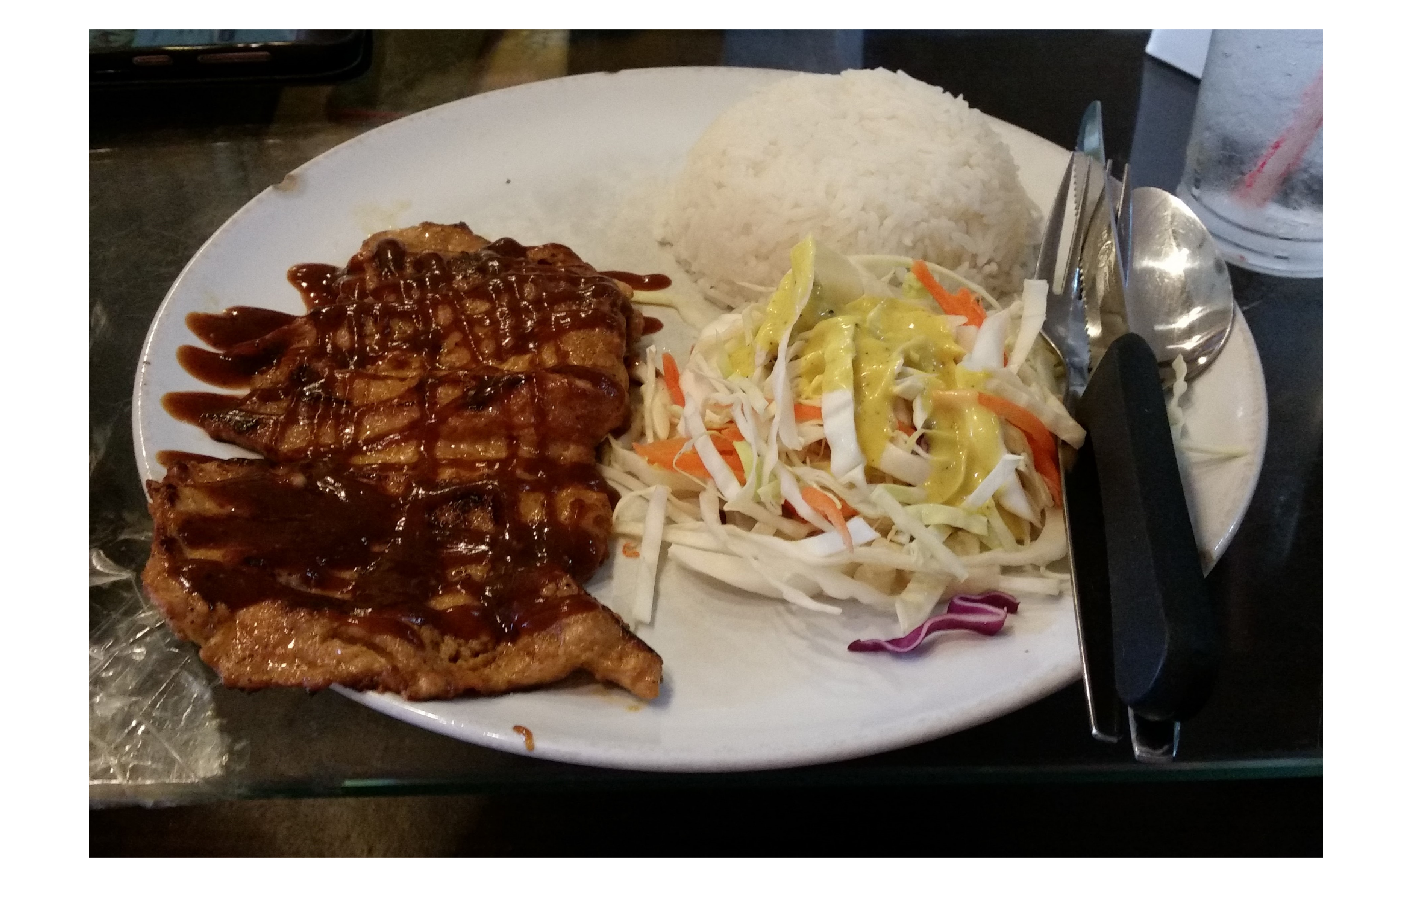

steak = find(imgDs.Labels == 'steak', 1);

figure
imshow(readimage(imgDs,steak))

## Count each Label

tbl = countEachLabel(imgDs)

tbl = 38×2 table
                    Label                     Count
    ______________________________________    _____

    barbecued_red_pork_in_sauce_with_rice      478 
    caesar_salad                               295 
    charcoal-boiled_pork_neck                  115 
    chow_mein                                  116 
    coconut_milk_soup                          111 
    crispy_pork_with_kale_with_rice            452 
    fried_chicken_with_rice                    347 
    fried_mussel_pancakes                      104 
    fried_pork_with_rice                       429 
    fried_rice                                1921 
    green_curry                                100 
    hamburger                                  267 
    hot_and_sour_fish_and_vegetable_ragout     113 
    kebab                                      251 
    khao_soi                                   118 
    noodles                   

## Load Pretrained Network

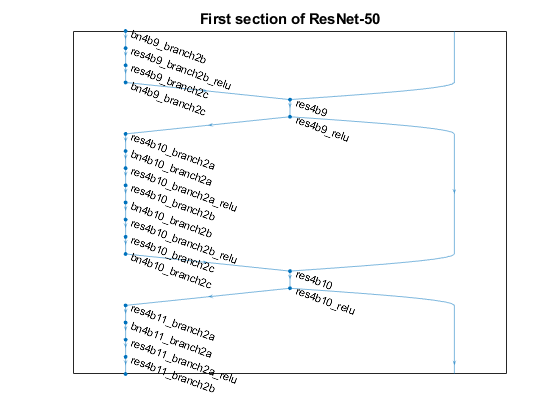

net = resnet101();

% Visualize the first section of the network. 
figure
plot(net)
title('First section of ResNet-50')
set(gca,'YLim',[150 170]);


net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


net.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'ClassificationLayer_predictions'
         Classes: [1000×1 categorical]
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'


numel(net.Layers(end).ClassNames)

ans = 1000

## Preparing Training and Testing set

[trainingSet, testSet] = splitEachLabel(imgDs, 0.7, 'randomize');

% Create augmentedImageDatastore from training and test sets to resize
% images in imds to the size required by the network.
imageSize = net.Layers(1).InputSize;
augmentedTrainingSet = augmentedImageDatastore(imageSize, trainingSet, "OutputSizeMode", "centercrop");
augmentedTestSet = augmentedImageDatastore(imageSize, testSet, "OutputSizeMode", "centercrop");

%% Get the activation of the last fully-connected layer
featureLayer = 'fc1000';
trainingFeatures = activations(net, augmentedTrainingSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

% Get training labels from the trainingSet
trainingLabels = trainingSet.Labels

trainingLabels = 8670×1 categorical array
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_w


% Train multiclass SVM classifier using a fast linear solver, and set
% 'ObservationsIn' to 'columns' to match the arrangement used for training
% features.

% t = templateSVM('KernelFunction','linear')


classifier = fitcecoc(trainingFeatures, trainingLabels, ...
    'Learners', 'linear', 'Coding', 'onevsall', 'ObservationsIn', 'columns');

% Extract test features using the CNN
testFeatures = activations(net, augmentedTestSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

% Pass CNN image features to trained classifier
predictedLabels = predict(classifier, testFeatures, 'ObservationsIn', 'columns');

% Get the known labels
testLabels = testSet.Labels;

% Tabulate the results using a confusion matrix.
confMat = confusionmat(testLabels, predictedLabels);

% Convert confusion matrix into percentage form
confMat = bsxfun(@rdivide,confMat,sum(confMat,2))

confMat =     0.1329         0         0         0         0         0    0.0420         0    0.2797         0         0         0         0         0         0         0         0    0.2308    0.0559         0         0         0         0         0    0.1678    0.0559         0         0    0.0070    0.0070         0         0         0    0.0140         0         0         0    0.0070
         0    0.7841         0         0    0.0114         0         0         0    0.0341         0         0    0.0341         0         0         0         0         0    0.0114    0.0341    0.0114         0    0.0227         0         0         0    0.0341         0    0.0114         0         0         0         0    0.0114         0         0         0         0         0
         0         0    0.4412         0    0.0294         0         0         0    0.1765         0         0    0.0588         0         0         0         0         0         0         0    0.0294         0    0.0882        

mean(diag(confMat))

ans = 0.5810